## Parameters and Equilibrium Conditions

P4 = [2 1 1 1 0.5 1];
E1 = [0 0 0];
E2 = [0 pi pi];
case7 = num2cell([P4,E1]);
case8 = num2cell([P4,E2]);

u = 0;
C = [1 0 0 0 0 0]; 
D = 0;
tmax = 15;

## Case 7: P4, E1

[m0, m1, m2, l1, l2, g, ye, theta1e, theta2e] = deal(case7{:});
mt = m0 + m1 + m2;
M = [mt, -m1*l1*cos(theta1e), -m2*l2*cos(theta2e);
    -m1*l1*cos(theta1e), m1*l1^2, 0;
    -m2*l2*cos(theta2e), 0, m2*l2^2];
G = [0,0,0;0,m1*l1*g*cos(theta1e),0;0,0,m2*l2*g*cos(theta2e)];
W = [1 0 0]';
A = [zeros(3), eye(3); M^-1*(-G), zeros(3)];
B = [0;0;0;M^-1*W];
[v,d] = eig(A)  

v =    1.0000 + 0.0000i  -1.0000 + 0.0000i  -0.0000 - 0.0893i  -0.0000 + 0.0893i  -0.0000 + 0.1040i  -0.0000 - 0.1040i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.1284i  -0.0000 + 0.1284i  -0.0000 + 0.5782i  -0.0000 - 0.5782i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.4573i  -0.0000 + 0.4573i   0.0000 - 0.3247i   0.0000 + 0.3247i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.1617 - 0.0000i   0.1617 + 0.0000i  -0.1148 - 0.0000i  -0.1148 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.2326 - 0.0000i   0.2326 + 0.0000i  -0.6385 + 0.0000i  -0.6385 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.8283 + 0.0000i   0.8283 + 0.0000i   0.3585 + 0.0000i   0.3585 - 0.0000i


d =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 1.8113i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 1.8113i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 1.1042i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 1.1042i


2*real(v(:,3))

ans =    -0.0000
   -0.0000
   -0.0000
    0.3234
    0.4652
    1.6567


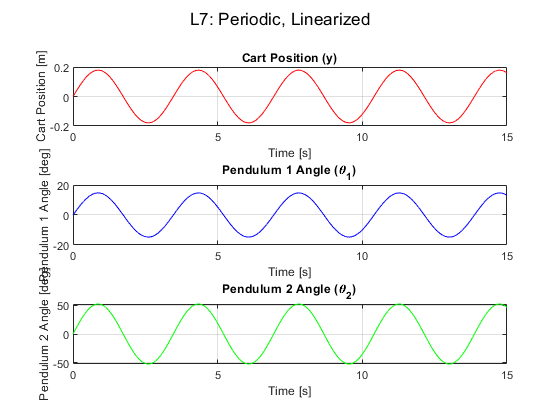

IC = v(:,3)+v(:,4);
t = linspace(0,tmax,2^12);
[t,x] = ode45(@(t,x) xfun(x,A,B),t,IC);

figure
subplot(3,1,1)
plot(t,x(:,1),'r')
title('Cart Position (y)')
xlabel('Time [s]')
ylabel('Cart Position [m]')
grid on
subplot(3,1,2)
plot(t,rad2deg(x(:,2)),'b')
title('Pendulum 1 Angle (\theta_{1})')
xlabel('Time [s]')
ylabel('Pendulum 1 Angle [deg]')
grid on
subplot(3,1,3)
plot(t,rad2deg(x(:,3)),'g')
title('Pendulum 2 Angle (\theta_{2})')
xlabel('Time [s]')
ylabel('Pendulum 2 Angle [deg]')
grid on
sgtitle('L7: Periodic, Linearized')

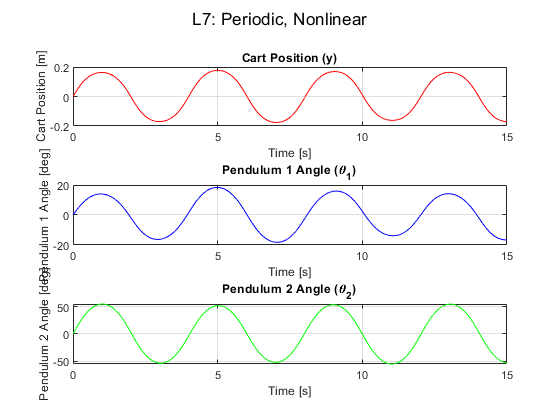

figure
[t,x] = ode45(@(t,x) xfun2(x, m0, m1, m2, l1, l2, g, mt),t,IC);
subplot(3,1,1)
plot(t,x(:,1),'r')
title('Cart Position (y)')
xlabel('Time [s]')
ylabel('Cart Position [m]')
grid on
subplot(3,1,2)
plot(t,rad2deg(x(:,2)),'b')
title('Pendulum 1 Angle (\theta_{1})')
xlabel('Time [s]')
ylabel('Pendulum 1 Angle [deg]')
grid on
subplot(3,1,3)
plot(t,rad2deg(x(:,3)),'g')
title('Pendulum 2 Angle (\theta_{2})')
xlabel('Time [s]')
ylabel('Pendulum 2 Angle [deg]')
grid on
sgtitle('L7: Periodic, Nonlinear')

## Case 8: P4, E2

[m0, m1, m2, l1, l2, g, ye, theta1e, theta2e] = deal(case8{:});
mt = m0 + m1 + m2;
M = [mt, -m1*l1*cos(theta1e), -m2*l2*cos(theta2e);
    -m1*l1*cos(theta1e), m1*l1^2, 0;
    -m2*l2*cos(theta2e), 0, m2*l2^2];
G = [0,0,0;0,m1*l1*g*cos(theta1e),0;0,0,m2*l2*g*cos(theta2e)];
W = [1 0 0]';
A = [zeros(3), eye(3); M^-1*(-G), zeros(3)]

A =          0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
         0   -0.5000   -0.5000         0         0         0
         0    1.5000    0.5000         0         0         0
         0    1.0000    3.0000         0         0         0


B = [0;0;0;M^-1*W]

B =          0
         0
         0
    0.5000
   -0.5000
   -1.0000


[v,d] = eig(A)

v =     1.0000   -1.0000    0.0893   -0.1040    0.0893   -0.1040
         0         0   -0.1284    0.5782   -0.1284    0.5782
         0         0   -0.4573   -0.3247   -0.4573   -0.3247
         0    0.0000    0.1617   -0.1148   -0.1617    0.1148
         0         0   -0.2326    0.6385    0.2326   -0.6385
         0         0   -0.8283   -0.3585    0.8283    0.3585


d =          0         0         0         0         0         0
         0         0         0         0         0         0
         0         0    1.8113         0         0         0
         0         0         0    1.1042         0         0
         0         0         0         0   -1.8113         0
         0         0         0         0         0   -1.1042


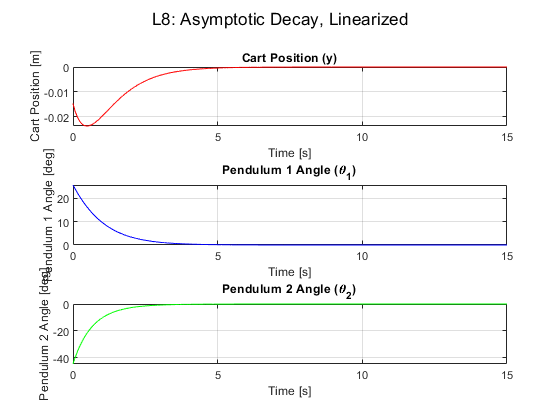

IC = v(:,5)+v(:,6);
t = linspace(0,tmax,2^12);
[t,x] = ode45(@(t,x) xfun(x,A,B),t,IC);

figure
subplot(3,1,1)
plot(t,x(:,1),'r')
title('Cart Position (y)')
xlabel('Time [s]')
ylabel('Cart Position [m]')
grid on
subplot(3,1,2)
plot(t,rad2deg(x(:,2)),'b')
title('Pendulum 1 Angle (\theta_{1})')
xlabel('Time [s]')
ylabel('Pendulum 1 Angle [deg]')
grid on
subplot(3,1,3)
plot(t,rad2deg(x(:,3)),'g')
title('Pendulum 2 Angle (\theta_{2})')
xlabel('Time [s]')
ylabel('Pendulum 2 Angle [deg]')
grid on
sgtitle('L8: Asymptotic Decay, Linearized')

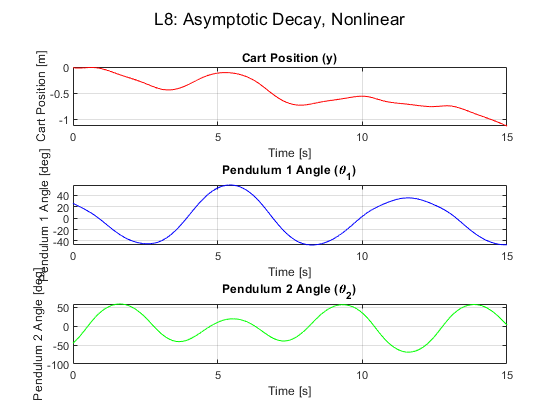

figure
[t,x] = ode45(@(t,x) xfun2(x, m0, m1, m2, l1, l2, g, mt),t,IC);
subplot(3,1,1)
plot(t,x(:,1),'r')
title('Cart Position (y)')
xlabel('Time [s]')
ylabel('Cart Position [m]')
grid on
subplot(3,1,2)
plot(t,rad2deg(x(:,2)),'b')
title('Pendulum 1 Angle (\theta_{1})')
xlabel('Time [s]')
ylabel('Pendulum 1 Angle [deg]')
grid on
subplot(3,1,3)
plot(t,rad2deg(x(:,3)),'g')
title('Pendulum 2 Angle (\theta_{2})')
xlabel('Time [s]')
ylabel('Pendulum 2 Angle [deg]')
grid on
sgtitle('L8: Asymptotic Decay, Nonlinear')

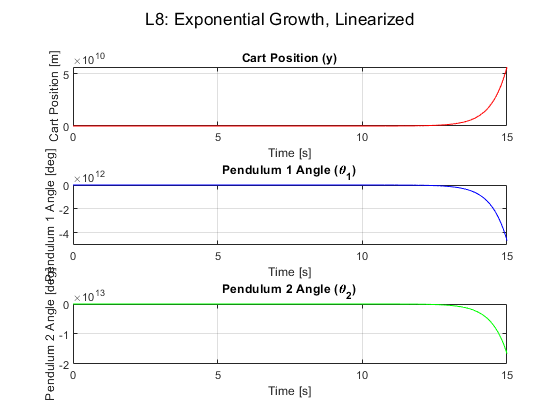

IC = v(:,3);
t = linspace(0,tmax,2^12);
[t,x] = ode45(@(t,x) xfun(x,A,B),t,IC);

figure
subplot(3,1,1)
plot(t,x(:,1),'r')
title('Cart Position (y)')
xlabel('Time [s]')
ylabel('Cart Position [m]')
grid on
subplot(3,1,2)
plot(t,rad2deg(x(:,2)),'b')
title('Pendulum 1 Angle (\theta_{1})')
xlabel('Time [s]')
ylabel('Pendulum 1 Angle [deg]')
grid on
subplot(3,1,3)
plot(t,rad2deg(x(:,3)),'g')
title('Pendulum 2 Angle (\theta_{2})')
xlabel('Time [s]')
ylabel('Pendulum 2 Angle [deg]')
grid on
sgtitle('L8: Exponential Growth, Linearized')

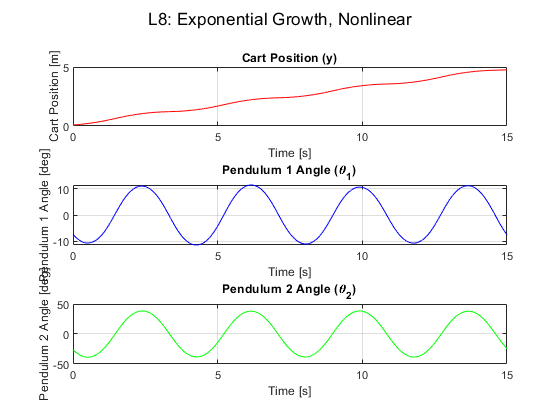

figure
[t,x] = ode45(@(t,x) xfun2(x, m0, m1, m2, l1, l2, g, mt),t,IC);
subplot(3,1,1)
plot(t,x(:,1),'r')
title('Cart Position (y)')
xlabel('Time [s]')
ylabel('Cart Position [m]')
grid on
subplot(3,1,2)
plot(t,rad2deg(x(:,2)),'b')
title('Pendulum 1 Angle (\theta_{1})')
xlabel('Time [s]')
ylabel('Pendulum 1 Angle [deg]')
grid on
subplot(3,1,3)
plot(t,rad2deg(x(:,3)),'g')
title('Pendulum 2 Angle (\theta_{2})')
xlabel('Time [s]')
ylabel('Pendulum 2 Angle [deg]')
grid on
sgtitle('L8: Exponential Growth, Nonlinear')

## Linearized

function dxdt = xfun(x,A,B)
u = 0;
dxdt = A*x + B*u;
end

## Nonlinear

function dxdt = xfun2(x, m0, m1, m2, l1, l2, g, mt)
u = 0;
M = [mt, -m1*l1*cos(x(2)), -m2*l2*cos(x(3));
 -m1*l1*cos(x(2)), m1*l1^2, 0;
 -m2*l2*cos(x(3)), 0, m2*l2^2];
G = [m1*l1*sin(x(2))*x(5)^2 + m2*l2*sin(x(3))*x(6)^2;
 m1*l1*g*sin(x(2));
 m2*l2*g*sin(x(3))];
W = [1;0;0];
q = x(1:3);
qdot = x(4:6);
qddot = inv(M)*(W*u-G);
dxdt = [qdot; qddot];
end